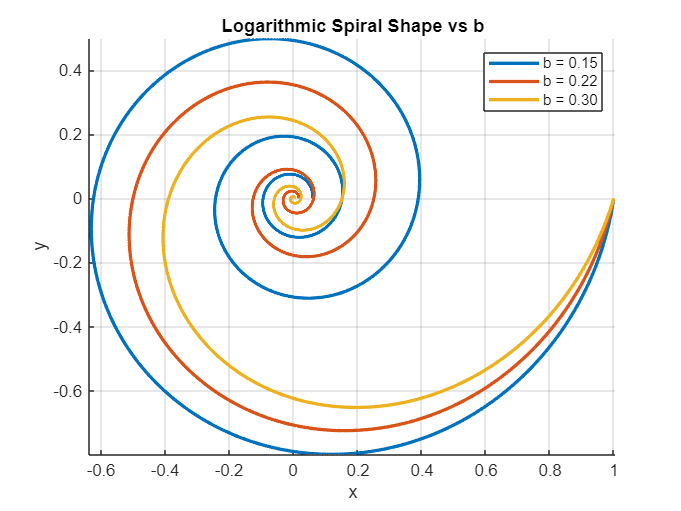

%% =========================================================
% SpiRob Geometry
% STAGE 1 — Logarithmic Spiral
% STAGE 2 — Robot Geometry Construction (2-Cable, Planar)
%
% Based strictly on:
% "SpiRobs: Logarithmic spiral-shaped robots for versatile grasping across scales"
% Device, 2025
%% =========================================================

clear; clc; close all;

%% =========================
% STAGE 1 — SPIRAL GEOMETRY
% =========================

a = 1;                              % scaling factor
theta = linspace(-6*pi, 0, 2000);   % base -> tip
b_values = [0.15 0.22 0.30];

%% ---- Spiral shape vs b ----
figure; hold on; axis equal; grid on;
for b = b_values
    r = a * exp(b * theta);
    [x,y] = pol2cart(theta, r);
    plot(x, y, 'LineWidth', 2);
end
legend('b = 0.15','b = 0.22','b = 0.30');
title('Logarithmic Spiral Shape vs b');
xlabel('x'); ylabel('y');

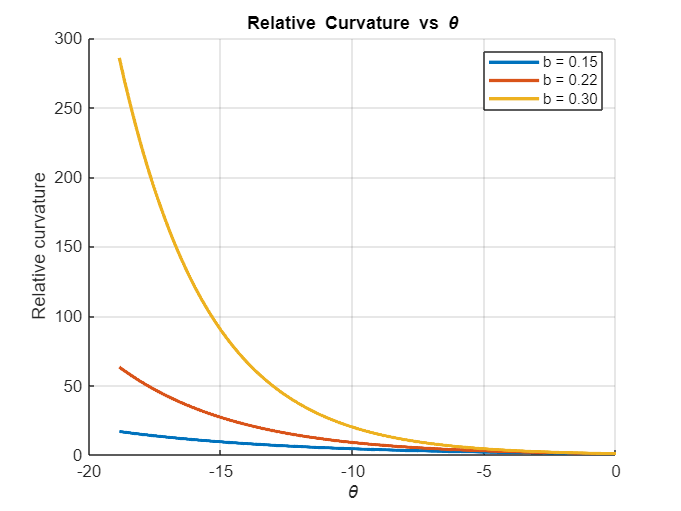


%% ---- Curvature vs theta (relative) ----
figure; hold on; grid on;
for b = b_values
    k = exp(-b * theta);   % normalized curvature trend
    plot(theta, k, 'LineWidth', 2);
end
legend('b = 0.15','b = 0.22','b = 0.30');
title('Relative Curvature vs \theta');
xlabel('\theta'); ylabel('Relative curvature');

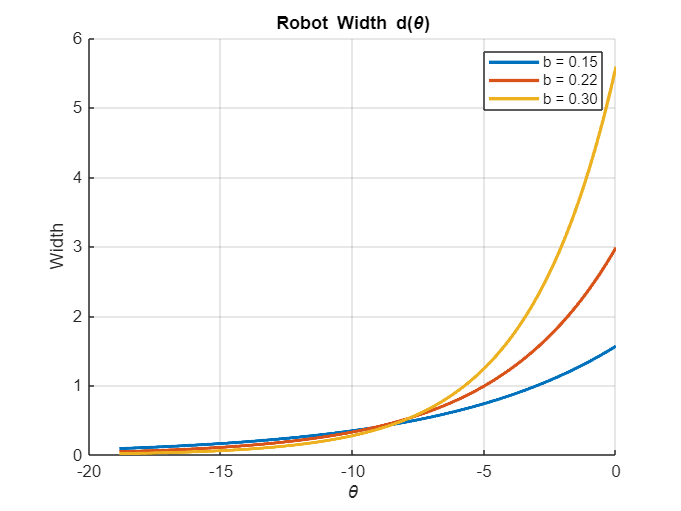


%% ---- Width vs theta ----
figure; hold on; grid on;
for b = b_values
    r1 = a * exp(b * theta);
    r2 = a * exp(b * (theta + 2*pi));
    d = r2 - r1;
    plot(theta, d, 'LineWidth', 2);
end
legend('b = 0.15','b = 0.22','b = 0.30');
title('Robot Width d(\theta)');
xlabel('\theta'); ylabel('Width');

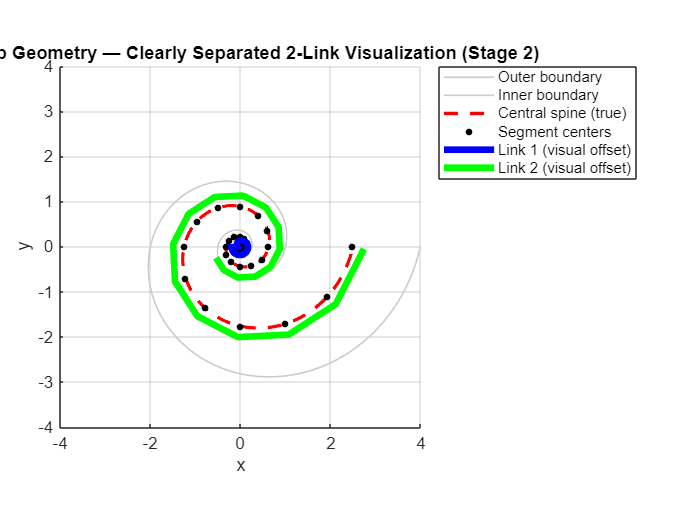


%% =====================================================
% STAGE 2 — SPIROB GEOMETRY CONSTRUCTION
% =====================================================

b = 0.22;                     % approved balanced value
dtheta = deg2rad(30);          % paper default discretization

%% ---- Spiral definitions ----
r_in  = a * exp(b * theta);
r_out = a * exp(b * (theta + 2*pi));
r_c   = 0.5 * (r_in + r_out);  % central spine (paper)

[x_in,  y_in]  = pol2cart(theta, r_in);
[x_out, y_out] = pol2cart(theta, r_out);
[x_c,   y_c]   = pol2cart(theta, r_c);

%% ---- Discretized central spine ----
theta_d = theta(1):dtheta:theta(end);
r_c_d = a * (exp(b * theta_d) + exp(b * (theta_d + 2*pi))) / 2;
[x_d, y_d] = pol2cart(theta_d, r_c_d);

%% ---- 2-link abstraction ----
N = length(theta_d);
split = round(N/2);
link1 = 1:split;
link2 = split+1:N;

%% =====================================================
% CLEAN, INTERPRETABLE GEOMETRY PLOT
% =====================================================
%% =====================================================
% STAGE 2 — FINAL, CLEAR VISUAL LINK SEPARATION
% =====================================================

figure; hold on; axis equal; grid on;

% ---- Boundaries (background context) ----
plot(x_out, y_out, 'Color',[0.8 0.8 0.8], 'LineWidth',1);
plot(x_in,  y_in,  'Color',[0.8 0.8 0.8], 'LineWidth',1);

% ---- True central spine ----
plot(x_c, y_c, 'r--', 'LineWidth',2);

% ---- Segment centers (de-emphasized) ----
plot(x_d, y_d, 'k.', 'MarkerSize',12);

%% ---- Compute normals for visual offset ----
dx = gradient(x_c);
dy = gradient(y_c);
n = sqrt(dx.^2 + dy.^2);
nx = -dy ./ n;
ny =  dx ./ n;

offset = 0.25;   % VISUAL OFFSET (large enough to see clearly)

% Match normals to discretized points
nx_d = interp1(theta, nx, theta_d);
ny_d = interp1(theta, ny, theta_d);

% Offset links (visual only)
x_link1 = x_d(link1) + offset * nx_d(link1);
y_link1 = y_d(link1) + offset * ny_d(link1);

x_link2 = x_d(link2) - offset * nx_d(link2);
y_link2 = y_d(link2) - offset * ny_d(link2);

%% ---- PLOT LINKS LAST (CRITICAL) ----
plot(x_link1, y_link1, 'b-', 'LineWidth',4);
plot(x_link2, y_link2, 'g-', 'LineWidth',4);

% ---- View ----
xlim([-4 4]);
ylim([-4 4]);

legend({'Outer boundary','Inner boundary','Central spine (true)',...
        'Segment centers','Link 1 (visual offset)','Link 2 (visual offset)'},...
        'Location','northeastoutside');

title('SpiRob Geometry — Clearly Separated 2-Link Visualization (Stage 2)');
xlabel('x'); ylabel('y');

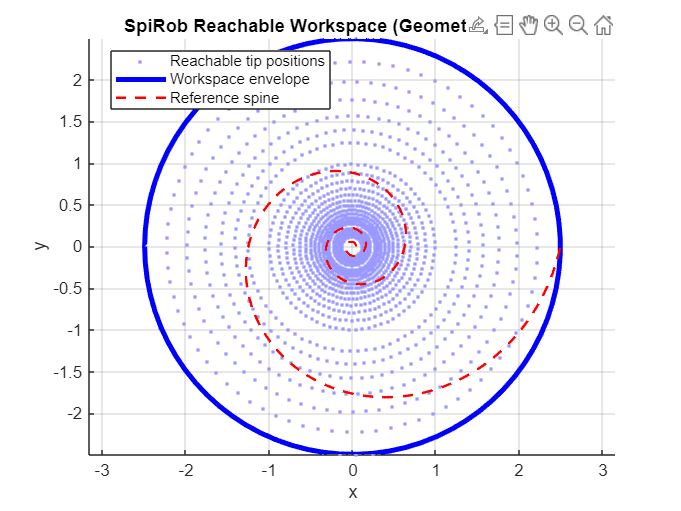

%% =====================================================
% STAGE 3 — WORKSPACE & REACH ENVELOPE (GEOMETRIC)
% =====================================================

% Use previously defined:
% x_c, y_c     -> central spine
% x_d, y_d     -> discretized spine
% link2        -> tip region indices

%% Parameters for workspace sampling
phi_vals = linspace(-pi, pi, 80);   % planar orientation
length_ratios = linspace(0.3, 1.0, 25);  % partial uncurling

tip_points = [];

%% Generate reachable tip positions
for phi = phi_vals
    R = [cos(phi) -sin(phi); sin(phi) cos(phi)];
    
    for lr = length_ratios
        idx = max(2, round(lr * length(x_d)));
        
        tip_local = [x_d(idx); y_d(idx)];
        tip_global = R * tip_local;
        
        tip_points = [tip_points; tip_global'];
    end
end

%% Convex hull of reachable workspace
K = convhull(tip_points(:,1), tip_points(:,2));

%% =====================================================
% WORKSPACE PLOT
% =====================================================

figure; hold on; axis equal; grid on;

% Scatter reachable points
plot(tip_points(:,1), tip_points(:,2), '.', ...
     'Color',[0.6 0.6 1], 'MarkerSize',6);

% Workspace envelope
plot(tip_points(K,1), tip_points(K,2), 'b', 'LineWidth',3);

% Plot reference robot shape
plot(x_c, y_c, 'r--', 'LineWidth',1.5);

xlabel('x'); ylabel('y');
title('SpiRob Reachable Workspace (Geometric Envelope)');
legend({'Reachable tip positions','Workspace envelope','Reference spine'},...
       'Location','best');

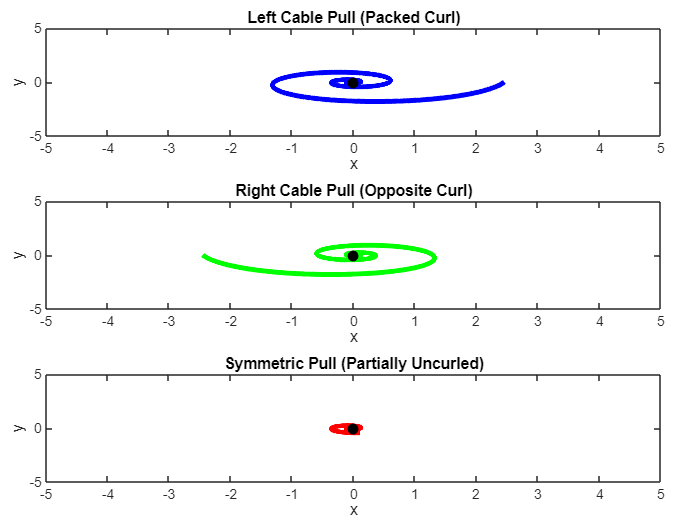

%% =====================================================
% STAGE 4 — STATIC CURLING STATES (BASE FIXED)
% =====================================================

% Central spine (true geometry)
%% =====================================================
% STAGE 4 — STATIC CURLING STATES (BASE FIXED, CORRECT)
% =====================================================

% Central spine
x = x_c;
y = y_c;

% ---- Identify base correctly ----
% Base = largest radius = first point in theta = -6π
x_base = x(1);
y_base = y(1);

% ---- Anchor base at origin ----
x = x - x_base;
y = y - y_base;

%% ---- Opposite curl (mirror about base axis) ----
x_mirror = -x;
y_mirror =  y;

%% ---- Partial uncurl (use MOST of the body, not tiny part) ----
partial_ratio = 0.6;  % 60% extended (physically meaningful)
partial_idx = round(partial_ratio * length(x));

x_partial = x(1:partial_idx);
y_partial = y(1:partial_idx);

%% =====================================================
% PLOT STATIC CONFIGURATIONS (NOW VISIBLE)
% =====================================================

figure; axis equal; grid on;
tiledlayout(3,1,'Padding','compact','TileSpacing','compact');

%% ---- LEFT CABLE PULL ----
nexttile;
plot(x, y, 'b', 'LineWidth',3);
hold on;
plot(0,0,'ko','MarkerFaceColor','k');
title('Left Cable Pull (Packed Curl)');
xlabel('x'); ylabel('y');
xlim([-5 5]); ylim([-5 5]);

%% ---- RIGHT CABLE PULL ----
nexttile;
plot(x_mirror, y_mirror, 'g', 'LineWidth',3);
hold on;
plot(0,0,'ko','MarkerFaceColor','k');
title('Right Cable Pull (Opposite Curl)');
xlabel('x'); ylabel('y');
xlim([-5 5]); ylim([-5 5]);

%% ---- SYMMETRIC PULL ----
nexttile;
plot(x_partial, y_partial, 'r', 'LineWidth',3);
hold on;
plot(0,0,'ko','MarkerFaceColor','k');
title('Symmetric Pull (Partially Uncurled)');
xlabel('x'); ylabel('y');
xlim([-5 5]); ylim([-5 5]);